## Static locking

We look at the balance between the axial spring and the radial spring to lock the claw in position

clear
clf

considering a constant spring constant we get the pull of one **axial spring** from SODEMANN

k_axial = 0.29e3; % N/mm --> N/m % max kraft 47,43, max vandring 140,97, total lenth 229,87
% varenummer 	E07500633500S trækfjeder SODEMANN
x_axial = 140e-3; % udspændt fjeder til træk af claw
F_spring_axial = k_axial * x_axial

F_spring_axial = 40.6000

considering a constant spring constant we get the push of one **radial spring** from SODEMANN

theta = 20; %angle on ball lock
r_ball = 5e-3; %radius of the ball lock % standard size

k_radial = 12.16e3; % N/mm --> N/m %max compresion 13.80, total length 27.00; max force 169,66
% varenummer 12410
% alternatvi C06000981750M	
% syms k_radial

x_radial = r_ball*sind(theta); %3; % mm compressed spring to hold
x_radial_mm = x_radial*1e3 % displayed movement in mm

x_radial_mm = 1.7101

F_spring_radial = k_radial*x_radial % the radial spring force

F_spring_radial = 20.7948

Frication acting on the calw is devided in to two kinds that are added up.

- Due to gravity we find

g = 9.82; % Gravity acceleration in denmark
m_claw = 1; %kg <--------- differ between claws
f_s = 0.20; %static / kinetic friction coeffecient %steel on steel
F_claw_fric = g * m_claw * f_s % friction due to the weigth of the claw

F_claw_fric = 1.9640

- Due to the process of sliding over the ball also ads the friction of the ball pushing up. 

The normal force comes from the spring pushing up and it veries with movement. But since the normal force is stronger then the friction force we will alway have more force to hold with less angle on theta.

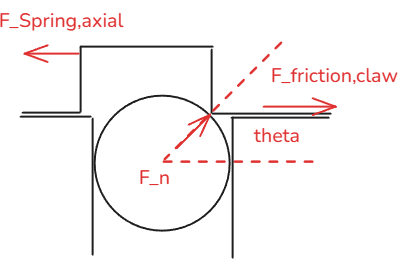

n=3600; % max rotation for 10kN torque tranducer
% n=180;
rho = 7.85e3;% kg/m^3 density of C45 acording to EDU pack
m = pi * 4/3 * r_ball^3 * rho % mass of the locking ball

m = 0.0041

omega = 2 * pi / 60 * n % rad/s % vinkel hastigheden

omega = 376.9911

r = 0.1; % distance to center of ball
a_n = r * omega^2; % Normal acceleration (radialt)
F_centri = a_n * m % centripetal force on ball

F_centri = 58.4158

F_centri_fric = F_centri * f_s % centripetal friction force due to ball

F_centri_fric = 11.6832

We sum the forces in the y-direction

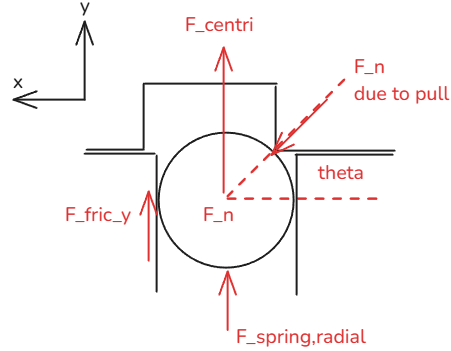

syms F_n F_n_y
F_n_x = F_n * cosd(theta); % The normal force needed in the x-direction, to keep the claw inplace
%if this is positve the ball claw is released.
% the balance should be slightly negative so it may holde duing running but
% is able to release when a little force is aplied
F_ball_fric_y = F_n_x * f_s; % friction of the ball in y direction due to axial force
F_n_y_eq = 0 == F_spring_radial + F_ball_fric_y + F_centri - F_n_y;

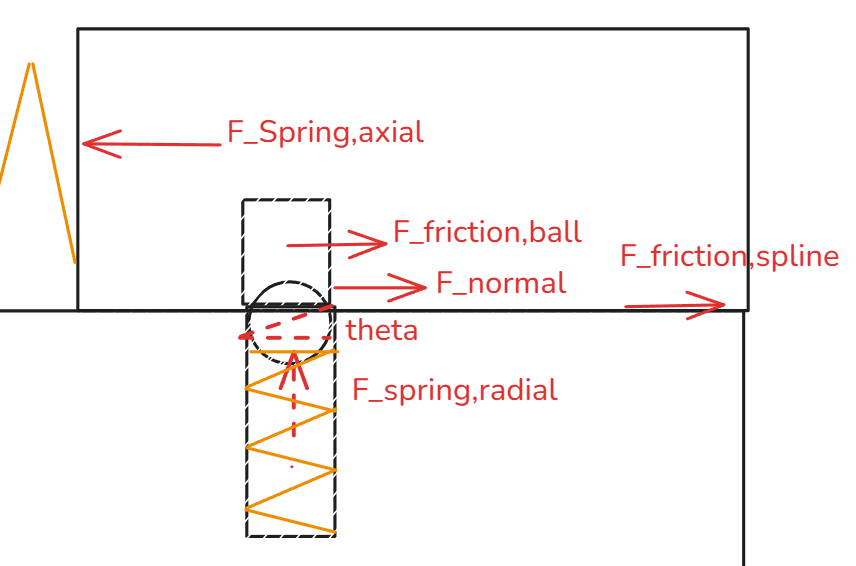

F_ball_fric_x = F_n_y * f_s; % friction on "roff" due to 
F_n_x_eq = 0 == F_spring_axial - F_ball_fric_x - F_claw_fric - F_n_x;

[F_n_sol, F_n_y_sol] = solve([F_n_x_eq, F_n_y_eq], [F_n, F_n_y]);
F_n_sol = double(F_n_sol);
F_n_y_sol = double(F_n_y_sol);
% F_n_sol = solve(F_n_x_eq, F_n);
% F_n_sol = double(F_n_sol);
F_n_x = F_n_sol * cosd(theta)

F_n_x = 21.9172

F_n_y = F_n_y_sol% * sind(thetas(i));

F_n_y = 83.5941


% F_n_sol = solve(F_n_x_eq, F_n);
% F_n = double(F_n_sol)
% F_n_y = F_n * sind(theta)
% F_n_x = F_n * cosd(theta)

## Plot

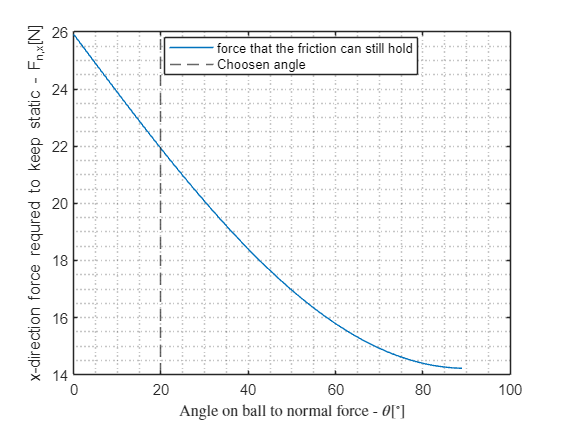

syms F_n F_n_y
thetas = 0:1:89; %angle on ball lock
for i = 1:length(thetas)
    x_radial = r_ball*sind(thetas(i)); %3; % mm compressed spring to hold
    F_spring_radial = k_radial*x_radial;
    % F_n_y = F_n * sind(thetas(i)); % + F_centri; % due to edge %F_n
    F_n_x = F_n * cosd(thetas(i)); % due to edge

    F_ball_fric_x = F_n_y * f_s;
    F_ball_fric_y = F_n_x * f_s;
    
    F_n_x_eq = 0 == F_spring_axial - F_ball_fric_x - F_claw_fric - F_n_x;
    F_n_y_eq = 0 == F_spring_radial + F_ball_fric_y + F_centri - F_n_y;
    
    [F_n_sol, F_n_y_sol] = solve([F_n_x_eq, F_n_y_eq], [F_n, F_n_y]);
    F_n_sol = double(F_n_sol);
    F_n_y_sol = double(F_n_y_sol);
    % F_n_sol = solve(F_n_x_eq, F_n);
    % F_n_sol = double(F_n_sol);
    F_n_xs(i) = F_n_sol * cosd(thetas(i));
    F_n_ys(i) = F_n_y_sol;% * sind(thetas(i));

    x_axials_move(i) = x_radial; %for later use
    F_ball_fric_x = F_n_y_sol * f_s; %for later use
    F_frictions(i) = F_ball_fric_x + F_claw_fric; %for later use
end

plot(thetas, F_n_xs, DisplayName="force that the friction can still hold")
hold on

xline(theta,'--', DisplayName="Choosen angle")
xlabel("Angle on ball to normal force - $\theta [^{\circ} ]$", Interpreter="latex")
ylabel("x-direction force requred to keep static - F_{n,x}[N]")
grid("minor")
legend(location='best')
hold off

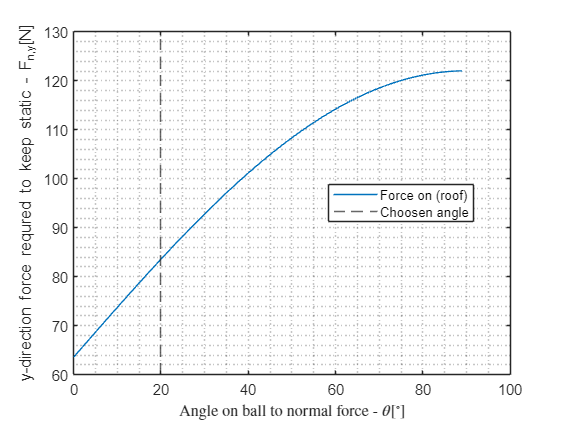



plot(thetas, F_n_ys, DisplayName="Force on (roof)")
hold on

xline(theta,'--', DisplayName="Choosen angle")
xlabel("Angle on ball to normal force - $\theta [^{\circ} ]$", Interpreter="latex")
ylabel("y-direction force requred to keep static - F_{n,y}[N]")
grid("minor")
legend(location='best')
hold off

This means that friction force of the ball can still handle a lot of force before moving.

It is also seen that the force to push down increases with the angle, this is due to a increased friction from the axial forces.

Dette skal ganges med 2 da der er fjeder både top og bund

For dynamik

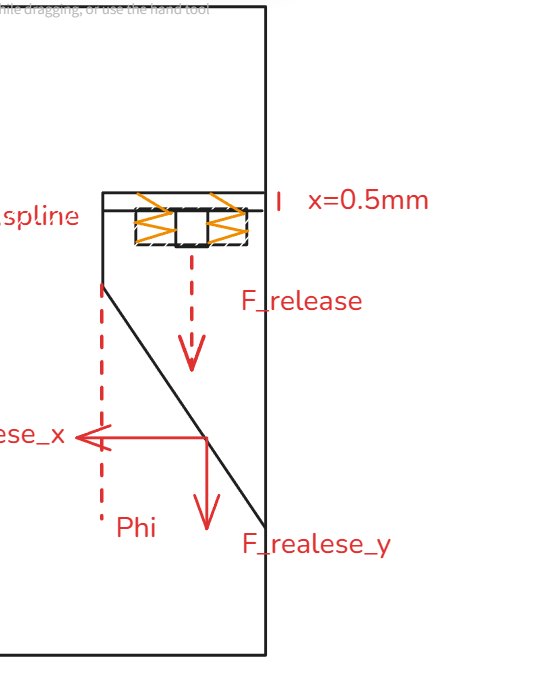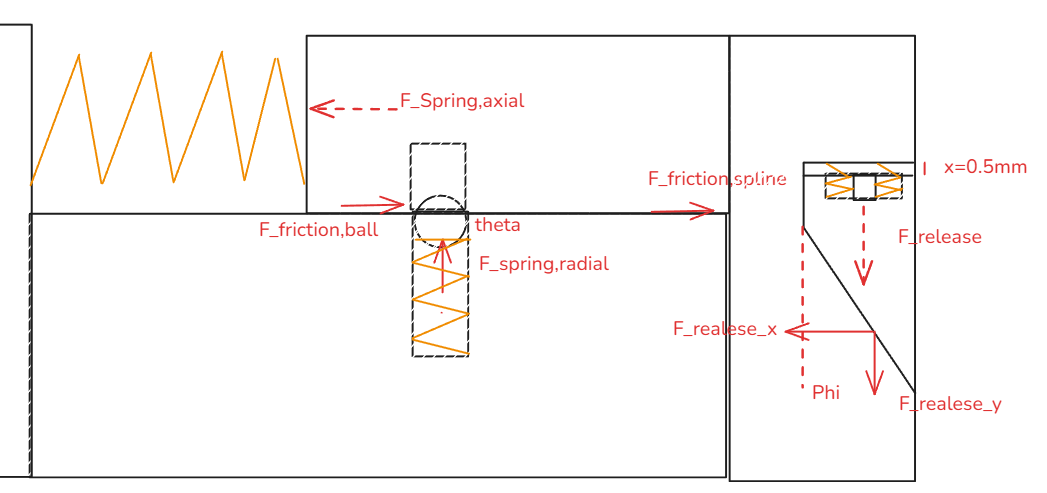

phi = 45

phi = 45


n_stack = 2; %number of stacked disc springs
F_realese = 553 * n_stack; % N = k * x  % max vandirng 0,53 ;frilængde 1,40, ved belastning 0,88, D_udvendig = 18,00mm
s = 0.53e-3;
% tallerken fjeder vare nummer 1800-620-70

F_realease_x = sind(phi) * F_realese

F_realease_x = 782.0601


F_realese_ball = F_realease_x / cosd(theta)

F_realese_ball = 832.2510

F_lock = max(abs(F_n_xs)) *2 %to overcome

F_lock = 51.8324

F_realease_ball_y = sind(theta) * F_realese_ball

F_realease_ball_y = 284.6466


% T = F_realese * r
W = F_realese * s % The work the spring does on the rotor

W = 0.5862


syms omega
% I = 1; % inertia of the test motor 
I = 3.68; % inertia of the test motor % HMC4 355L-2
% I = 12.79; % inertia of the test motor % HMC4 355L-6
% I = 15.9356; % inertia of the test motor % weigth of motor = 2158 kg <--------- differ from motor to motor
W_eq = W == 1/2 * I * omega^2;
omega_sol = solve(W_eq, omega);
omega = double(omega_sol(2))

omega = 0.5644

Dermed har jeg hastigheden ved slip, kraften aftager løbende i fjederen men antage at være tæt på F_realease_x i det kontakten slippes.

Couplings delen skal rejse 1 mm og tabet her negligeres

We see this as a totallly non-elastic collision because of the slow speeds and high moments of inertia.

m_rotor = 400; %                 <--------- differ from motor to motor
u_rotor = r * omega

u_rotor = 0.0564

u_rotor_x = sind(phi) * u_rotor

u_rotor_x = 0.0399

% where u_claw = 0 since we are seeing it from the claws point of veiw.
v_claw_x = m_rotor * u_rotor_x / (m_rotor + m_claw) 

v_claw_x = 0.0398

x_axial_move = x_radial

x_axial_move = 0.0050


E_kin_claw = 1/2 * m_claw * v_claw_x^2

E_kin_claw = 7.9247e-04


% E_radial_spring = 1/2 * k_radial * (x_radial)^2 * 2 %two springs

E_axial_spring = 1/2 * k_axial * (x_axial_move)^2 * 2 %two springs %

E_axial_spring = 0.0072


Friction_work_done = trapz(x_axials_move, F_frictions) % trapezoidal integration with matlab function

Friction_work_done = 0.1026

% Work done due to friction

Total = E_kin_claw + E_axial_spring - Friction_work_done

Total = -0.0946

limits for pulling and pushing of a worker in canada [https://www.ccohs.ca/oshanswers/ergonomics/push1.html](https://www.ccohs.ca/oshanswers/ergonomics/push1.html)

## Conklusion

Even beeing genereus the spring would not give enough energi to overcome the friction forces

If we use a bigger axial spring it would not be able to be countered by the friction forces when standing still and the centrifugal force is removed.